% Latex file in: 

[/home/joaquin/Desktop/CURRENT_TASKS/PAPERS_2020_onwards/OptimalECM/OPTIMALECM.tex](matlab:open('/home/joaquin/Desktop/CURRENT_TASKS/PAPERS_2020_onwards/OptimalECM/OPTIMALECM.tex'))

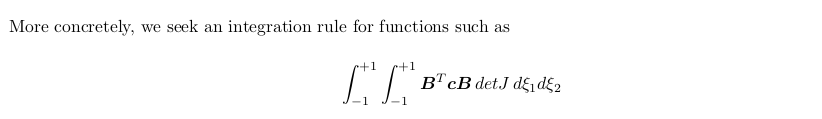

 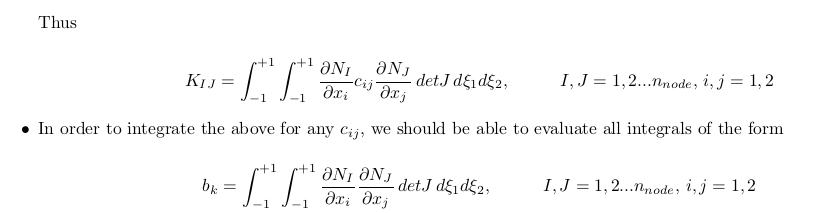

FUNCTION TO BE INTEGRATED 

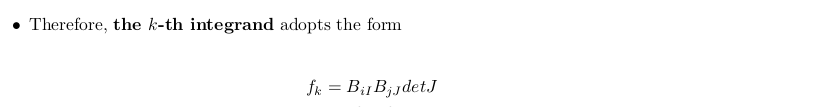

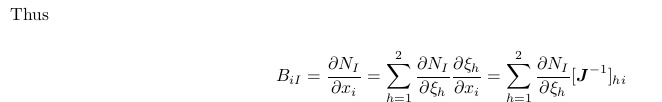

The derivatives with respect to the parent coordinates are calculated as follows


% 1) Nshape = M points x  nmonomials, i.e., number of shape functions
[Nshape, B_x,B_y,DATAOUTlagrag] =    LagrangePolynomial2D(xLIM,P,xMAT) ;

Cannot find an exact (case-sensitive) match for 'xLIM'

The closest match is: xlim in /usr/local/MATLAB/R2020b/toolbox/matlab/graph3d/xlim.m


% 2) Matrix of derivatives  (with respect to xi1_1 and xi_2 )
B_xi ={B_x ;B_y} ;  %

% 3) Matrix of second derivatives (with respect to xi1_1 and xi_2 )
H_xi = {DATAOUTlagrag.H_xx,DATAOUTlagrag.H_xy
       DATAOUTlagrag.H_xy,DATAOUTlagrag.H_yy} ; 

JAcobian matrix

% Jacobian matrix (vectorized)
ndim = 2;
npoints =size(xMAT,1) ;
J =zeros(ndim*npoints,ndim) ;
npointsE =  size(X,2) ;
ipoints = 1:npoints ;
for  idim = 1:ndim
    idimLOC = (ipoints-1)*ndim+idim ;
    for Ipoints = 1:npointsE
        for jdim = 1:ndim
            J(idimLOC,jdim) = J(idimLOC,jdim) + X(idim,Ipoints)*B_xi{jdim}(ipoints,Ipoints) ;
        end
    end
end

B = {zeros(size(B_xi{1})),zeros(size(B_xi{2}))} ; % Initialization 
ipoints = 1:npoints ;
for idim = 1:ndim    
    for Inodes = 1:npointsE
        for hdim = 1:ndim
            hdimGLO = (ipoints-1)*ndim+hdim ; 
            B{idim}(:,Inodes) = B{idim}(:,Inodes) + B_xi{hdim}(:,Inodes)*invJ(hdimGLO,idim) ; 
        end        
    end   
end

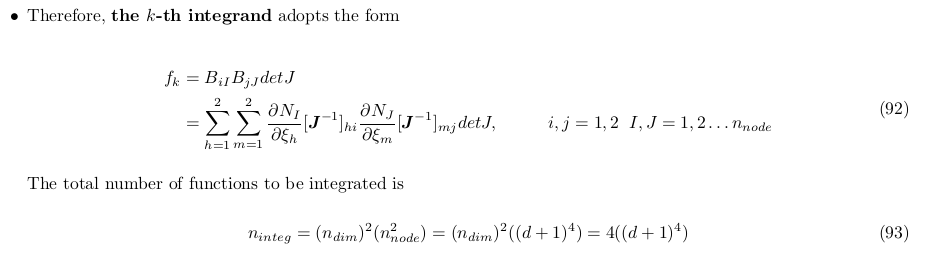

% Functions to be integrated 
% --------------------------
n_funct = ndim^2*(npointsE)^2; 
A = zeros(npoints,n_funct) ; 
kacum = 1; 

for idim = 1:ndim 
    for Inode = 1:npointsE
        for jdim = 1:ndim 
            for Jnode = 1:npointsE 
                A(:,kacum) = B{idim}(:,Inode).*B{jdim}(:,Jnode).*detJ ; 
                kacum = kacum + 1; 
            end
        end
    end
end


% DERIVATIVES 

% --------------------------------------------------------

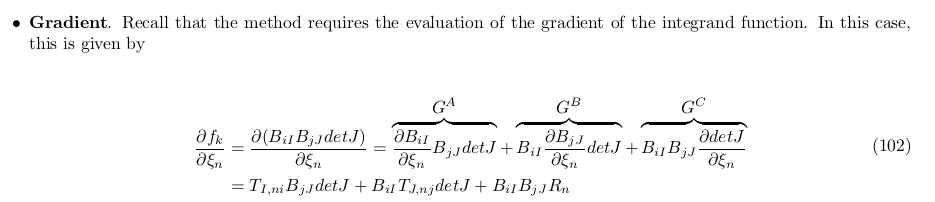

for idim = 1:ndim 
    for Inode = 1:npointsE
        for jdim = 1:ndim 
            for Jnode = 1:npointsE 
                A(:,kacum) = B{idim}(:,Inode).*B{jdim}(:,Jnode).*detJ ; 
                
                if  EVALUATE_GRADIENT == 1 
                    
                    for n_dim = 1:ndim 
                            dA{n_dim}(:,kacum) = T{n_dim,idim}(:,Inode).*B{jdim}(:,Jnode).*detJ ...   % G_A
                                        + B{idim}(:,Inode)*T{n_dim,jdim}(:,Jnode).*detJ ... % G_B
                                        + B{idim}(:,Inode).*B{jdim}(:,Jnode).*R{n_dim} ; % G_C 
                    end
                    
                end
                 
                
                kacum = kacum + 1; 
            end
        end
    end
end

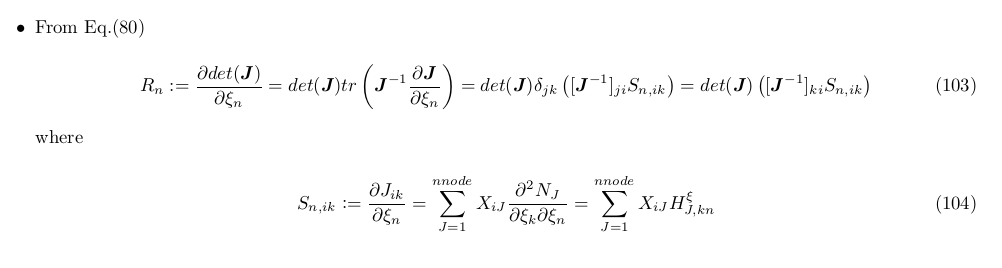

  for n_dim = 1:ndim
        S{n_dim} = zeros(size(J)) ;
        for idim = 1:ndim
            idimGLO = (ipoints-1)*ndim+idim ;
            for kdim = 1:ndim
                for Jnode = 1:npointsE
                    S{n_dim}(idimGLO,kdim) =  S{n_dim}(idimGLO,kdim)  + X(idim,Jnode).*H_xi{kdim,n_dim}(:,Jnode) ;
                end
            end
        end
        R{n_dim} =zeros(size(detJ)) ;    

for  kdim = 1:ndim
            kdimGLO = (ipoints-1)*ndim+kdim ;
            for idim = 1:ndim
                idimGLO = (ipoints-1)*ndim+idim ;
               %  R{n_dim} =  R{n_dim} +
               %  J(kdimGLO,idim).*S{n_dim}(idimGLO,kdim);  % Before
               %  29-Oct-2021
                R{n_dim} =  R{n_dim} + invJ(kdimGLO,idim).*S{n_dim}(idimGLO,kdim);
                
            end
        end
        R{n_dim} =   R{n_dim}.*detJ ;

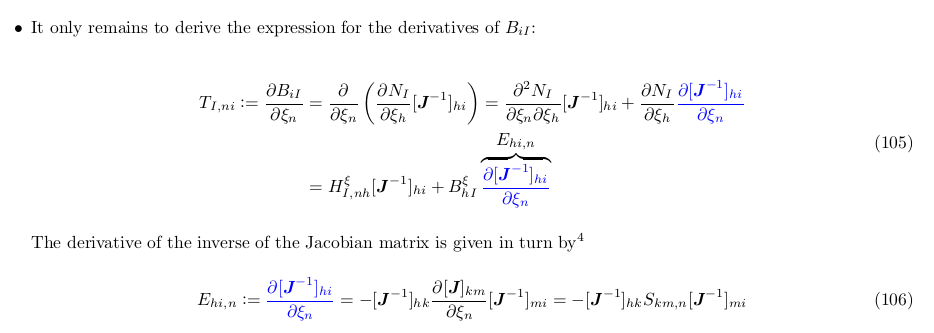

    E = cell(1,ndim) ;
    for n_dim = 1:ndim
        E{n_dim} = zeros(size(J)) ; 
        for hdim = 1:ndim 
            hdimGLO = (ipoints-1)*ndim+hdim ;
            for idim = 1:ndim 
                for kdim = 1:ndim 
                     kdimGLO = (ipoints-1)*ndim+kdim ;
                    for mdim  = 1:ndim 
                        mdimGLO = (ipoints-1)*ndim+mdim ;
                        E{n_dim}(hdimGLO,idim) =  E{n_dim}(hdimGLO,idim) ...
                                                  -invJ(hdimGLO,kdim).*S{n_dim}(kdimGLO,mdim).*invJ(mdimGLO,idim); 
                    end
                end
            end
        end 
    end
    
    
    
    T = cell(ndim,ndim) ; 
    
    for  n_dim = 1:ndim 
        for idim = 1:ndim
            T{n_dim,idim} = zeros(size(B{n_dim}));
           for Inode = 1:npointsE
               for hdim = 1:ndim
                   hdimGLO = (ipoints-1)*ndim+hdim ;
                   T{n_dim,idim} = T{n_dim,idim} + H_xi{n_dim,hdim}(:,Inode).*J(hdimGLO,idim) + B_xi{hdim}(:,Inode).*E{n_dim}(hdimGLO,idim) ; 
               end
           end
        end        
    end